close all;
clear variables;

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = 1; % 0.75 м %%% убрать 
phi_grad = 180;
angle = 65;

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

pc = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]},...
    'dphi', {[]}, 'phi_begin', {[]}, 'phi_end', {[]});
pc(1).int1 = [155, 0]/lambda;
pc(1).int2 = [294, 634]/lambda;
pc(1).centr = [1655, 0]/lambda;
pc(1).dphi = 25;

pc(2).int1 = [8901, 19088]/lambda;
pc(2).int2 = [10260, 19954]/lambda;
pc(2).centr = [10260, 18454]/lambda;
pc(2).dphi = 65;

pc(3).int1 = [12718, 19954]/lambda;
pc(3).int2 = [14218, 18454]/lambda;
pc(3).centr = [12718, 18454]/lambda;
pc(3).dphi = 90;

pc(4).int1 = [14218, 15829]/lambda;
pc(4).int2 = [14077, 15195]/lambda;
pc(4).centr = [12718, 15829]/lambda;
pc(4).dphi = 90;

pc(5).int1 = [7287, 634]/lambda;
pc(5).int2 = [7147, 0]/lambda;
pc(5).centr = [8647, 0]/lambda;
pc(5).dphi = 90;

l23 = sqrt((pc(2).int1(1) - pc(1).int2(1))^2 + (pc(2).int1(2) - pc(1).int2(2))^2);
l45 = sqrt((pc(3).int1(1) - pc(2).int2(1))^2 + (pc(3).int1(2) - pc(2).int2(2))^2);
l67 = sqrt((pc(4).int1(1) - pc(3).int2(1))^2 + (pc(4).int1(2) - pc(3).int2(2))^2);
l89 = sqrt((pc(5).int1(1) - pc(4).int2(1))^2 + (pc(5).int1(2) - pc(4).int2(2))^2);

R = 1500/lambda;

pci = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]},...
    'dphi', {[]}, 'phi_begin', {[]}, 'phi_end', {[]});
pci(1).int1 = [905, 0]/lambda;
pci(1).int2 = [975, 317]/lambda;
pci(1).centr = pc(1).centr/lambda;
pci(1).dphi = 25;

pci(2).int1 = [9581, 18771]/lambda;
pci(2).int2 = [10260, 19204]/lambda;
pci(2).centr = pc(2).centr/lambda;
pci(2).dphi = 65;

pci(3).int1 = [12718, 19204]/lambda;
pci(3).int2 = [13464, 18454]/lambda;
pci(3).centr = pc(3).centr/lambda;
pci(3).dphi = 90;

pci(4).int1 = [13468, 15830]/lambda;
pci(4).int2 = [13398, 15513]/lambda;
pci(4).centr = pc(4).centr/lambda;
pci(4).dphi = 90;

pci(5).int1 = [6608, 951]/lambda;
pci(5).int2 = [6391, 0]/lambda;
pci(5).centr = pc(5).centr/lambda;
pci(5).dphi = 90;

li23 = sqrt((pci(2).int1(1) - pci(1).int2(1))^2 + (pci(2).int1(2) - pci(1).int2(2))^2);
li45 = sqrt((pci(3).int1(1) - pci(2).int2(1))^2 + (pci(3).int1(2) - pci(2).int2(2))^2);
li67 = sqrt((pci(4).int1(1) - pci(3).int2(1))^2 + (pci(4).int1(2) - pci(3).int2(2))^2);
li89 = sqrt((pci(5).int1(1) - pci(4).int2(1))^2 + (pci(5).int1(2) - pci(4).int2(2))^2);

R2 = R/2;
R3 = R + R2;

% первая окружность (1/4 окружности)
phi_1_begin = 0; % относительно оси х
phi_1_end = acosd((pc(1).centr(1)-pc(1).int2(1))/R);
dphi_1 = phi_1_end - phi_1_begin;

% вторая окружность 
phi_2_begin = acosd((pc(2).centr(1)-pc(2).int1(1))/R); % относительно оси х
phi_2_end = acosd((pc(2).centr(1)-pc(2).int2(1))/R);
dphi_2 = phi_2_end - phi_2_begin;

% третья окружность 
phi_3_begin = acosd((pc(3).centr(1)-pc(3).int1(1))/R); % относительно оси х
phi_3_end = acosd((pc(3).centr(1)-pc(3).int2(1))/R);
dphi_3 = phi_3_end - phi_3_begin;

% четверта окружность
phi_4_begin = acosd((pc(4).centr(1)-pc(4).int1(1))/R); % относительно оси х
phi_4_end = acosd((pc(4).centr(1)-pc(4).int2(1))/R);
dphi_4 = abs(phi_4_end - phi_4_begin);

% пятая окружность
phi_5_begin = acosd((pc(5).centr(1)-pc(5).int1(1))/R);
phi_5_end = acosd((pc(5).centr(1)-pc(5).int2(1))/R);
dphi_5 = abs(phi_5_end - phi_5_begin);

% окружности
N12 = 8;
N34 = 8;
N56 = 8;
N78 = 8;
N910 = 8;

% прямые
N23 = 8;
N45 = 8;
N67 = 8;
N89 = 8;

% окружности
N12_DE = 2*N12;
N34_DE = 2*N34;
N56_DE = 2*N56;
N78_DE = 2*N78;
N910_DE = 2*N910;

% прямые
N23_DE = 2*N23;
N45_DE = 2*N45;
N67_DE = 2*N67;
N89_DE = 2*N89;

#### Построение окружностей

%%% Построим дугу окружности 1

for i = 1 : N12
    phid_step = dphi_1/N12;
    t1 = phid_step*(i-0.5);
    x12(i) = R*cosd(-t1+180) + pc(1).centr(1);
    z12(i) = R*sind(-t1+180) + pc(1).centr(2);
    dx12(i) = 2*R*sind(dphi_1/2);
    tx12(i) = sind(phid_step*i);
    tz12(i) = cosd(phid_step*i);
end

for i = 1 : N34
    phid_step = dphi_2/N34;
    t2 = phi_2_begin + phid_step*(i-0.5);
    x34(i) = R*cosd(-t2+180) + pc(2).centr(1);
    z34(i) = R*sind(-t2+180) + pc(2).centr(2);
    dx34(i) = 2*R*sind(dphi_2/2);
    tx34(i) = sind(25 + phid_step*i);
    tz34(i) = cosd(25 + phid_step*i);
end


for i = 1 : N56
    phid_step = dphi_3/N56;
    t3 = phi_3_begin + phid_step*(i-0.5);
    x56(i) = R*cosd(-t3+180) + pc(3).centr(1);
    z56(i) = R*sind(-t3+180) + pc(3).centr(2);
    dx56(i) = 2*R*sind(dphi_3/2);
    tx56(i) = sind(90 + phid_step*i);
    tz56(i) = cosd(90 + phid_step*i);
end

for i = 1 : N78
    phid_step = dphi_4/N78;
    t4 =  phid_step*(i-0.5);
    x78(i) = R*cosd(-t4) + pc(4).centr(1);
    z78(i) = R*sind(-t4) + pc(4).centr(2);
    dx78(i) = 2*R*sind(dphi_4/2);
    tx78(i) = sind(180 + phid_step*i);
    tz78(i) = cosd(180 + phid_step*i);
end

for i = 1 : N910
    phid_step = dphi_5/N910;
    t5 = 90 + 65 + phid_step*(i-0.5);
    x910(i) = R*cosd(t5) + pc(5).centr(1);
    z910(i) = R*sind(t5) + pc(5).centr(2);
    dx910(i) = 2*R*sind(dphi_5/2);
    tx910(i) = -sind(phi_5_begin - phid_step*i);
    tz910(i) = -cosd(phi_5_begin - phid_step*i);
end

for i = 1 : N23
    step23 = l23/N23;
    x23(i) = pc(1).int2(1) + cosd(angle)*step23*(i-0.5);
    z23(i) = pc(1).int2(2) + sind(angle)*step23*(i-0.5);
    dx23(i) = step23;
    tx23(i) = cosd(angle);
    tz23(i) = sind(angle);
end

for i = 1 : N45
    step45 = l45/N45;
    x45(i) = pc(2).int2(1) + step45*(i-0.5);
    z45(i) = pc(2).int2(2);
    dx45(i) = step45;
    tx45(i) = 1;
    tz45(i) = 0;
end

for i = 1 : N67
    step67 = l67/N67;
    x67(i) = pc(3).int2(1);
    z67(i) = pc(3).int2(2) - step67*(i-0.5);
    dx67(i) = step67;
    tx67(i) = 0;
    tz67(i) = -1;
end

for i = 1 : N89
    step89 = l89/N89;
    x89(i) = pc(4).int2(1) - step89*(i-0.5)*cosd(angle);
    z89(i) = pc(4).int2(2) - step89*(i-0.5)*sind(angle);
    dx89(i) = step89;
    tx89(i) = -cosd(angle);
    tz89(i) = -sind(angle);
end

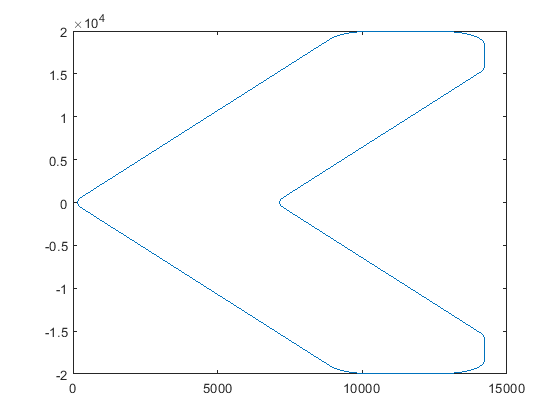

x_midle = horzcat(x12, x23, x34, x45, x56, x67, x78, x89, x910);
z_midle = horzcat(z12, z23, z34, z45, z56, z67, z78, z89, z910);
x_midle = horzcat(x_midle, flip(x_midle));
z_midle = horzcat(z_midle, flip(-z_midle));
tx = horzcat(tx12, tx23, tx34, tx45, tx56, tx67, tx78, tx89, tx910,...
            flip(-tx910), -tx89, flip(-tx78), tx67, flip(-tx56), -tx45, flip(-tx34), -tx23, flip(-tx23));
tz = horzcat(tz12, tz23, tz34, tz45, tz56, tz67, tz78, tz89, tz910,...
            flip(tz910), tz89, flip(tz78), tz67, flip(tz56), tz45, flip(tz34), tz23, flip(tz23));
N_l_all = length(x_midle);
plot(x_midle, z_midle)

name_file = strcat('tx.dat');
f04 = fopen(name_file,'w');

for n= 1 : length(x_midle)
    fprintf(f04,' %10.5f %10.5f\n', (n), tx(n));
end

fclose(f04);

name_file = strcat('tz.dat');
f04 = fopen(name_file,'w');

for n= 1 : length(x_midle)
    fprintf(f04,' %10.5f %10.5f\n', (n), tz(n));
end

fclose(f04);

ВИ

[x12, x23, x34, x45, x56, x67, x78, x89, x910,...
 z12, z23, z34, z45, z56, z67, z78, z89, z910] = deal(0);

for i = 1 : N12
    phid_step = dphi_1/N12;
    t1 = phid_step*(i-0.5);
    x12(i) = R2*cosd(-t1+180) + pc(1).centr(1);
    z12(i) = R2*sind(-t1+180) + pc(1).centr(2);
end

for i = 1 : N34
    phid_step = dphi_2/N34;
    t2 = phi_2_begin + phid_step*(i-0.5);
    x34(i) = R2*cosd(-t2+180) + pc(2).centr(1);
    z34(i) = R2*sind(-t2+180) + pc(2).centr(2);
end

for i = 1 : N56
    phid_step = dphi_3/N56;
    t3 = phi_3_begin + phid_step*(i-0.5);
    x56(i) = R2*cosd(-t3+180) + pc(3).centr(1);
    z56(i) = R2*sind(-t3+180) + pc(3).centr(2);
end

for i = 1 : N78
    phid_step = dphi_4/N78;
    t4 =  phid_step*(i-0.5);
    x78(i) = R2*cosd(-t4) + pc(4).centr(1);
    z78(i) = R2*sind(-t4) + pc(4).centr(2);
end


for i = 1 : N910
    phid_step = dphi_5/N910;
    t5 = 90 + 65 + phid_step*(i-0.5);
    x910(i) = R3*cosd(t5) + pc(5).centr(1);
    z910(i) = R3*sind(t5) + pc(5).centr(2);
end

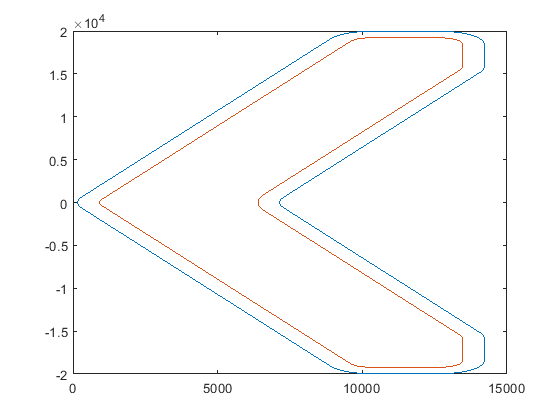


for i = 1 : N23
    step23 = li23/N23;
    x23(i) = pci(1).int2(1) + cosd(angle)*step23*(i-0.5);
    z23(i) = pci(1).int2(2) + sind(angle)*step23*(i-0.5);
end

for i = 1 : N45
    step45 = li45/N45;
    x45(i) = pci(2).int2(1) + step45*(i-0.5);
    z45(i) = pci(2).int2(2);
    dx45(i) = step45;
    tx45(i) = 1;
    tz45(i) = 0;
end

for i = 1 : N67
    step67 = li67/N67;
    x67(i) = pci(3).int2(1);
    z67(i) = pci(3).int2(2) - step67*(i-0.5);
end

for i = 1 : N89
    step89 = li89/N89;
    x89(i) = pci(4).int2(1) - step89*(i-0.5)*cosd(angle);
    z89(i) = pci(4).int2(2) - step89*(i-0.5)*sind(angle);
end

x_midle_i = horzcat(x12, x23, x34, x45, x56, x67, x78, x89, x910);
z_midle_i = horzcat(z12, z23, z34, z45, z56, z67, z78, z89, z910);
x_midle_i = horzcat(x_midle_i, flip(x_midle_i));
z_midle_i = horzcat(z_midle_i, flip(-z_midle_i));
N_i_all = length(x_midle_i);

plot(x_midle, z_midle,x_midle_i, z_midle_i)

DE

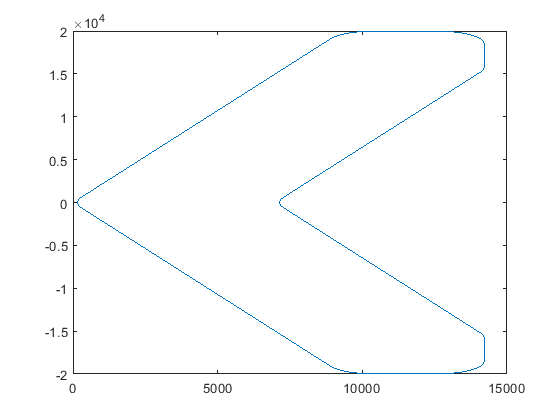

[x12, x23, x34, x45, x56, x67, x78, x89, x910,...
 z12, z23, z34, z45, z56, z67, z78, z89, z910] = deal(0);
[tx12, tx23, tx34, tx45, tx56, tx67, tx78, tx89, tx910,...
 tz12, tz23, tz34, tz45, tz56, tz67, tz78, tz89, tz910] = deal(0);


%%% Построим дугу окружности 1

for i = 1 : N12_DE-1
    phid_step = dphi_1/N12_DE;
    t1 = phid_step*(i);
    x12(i) = R*cosd(-t1+180) + pc(1).centr(1);
    z12(i) = R*sind(-t1+180) + pc(1).centr(2);
    dx12(i) = 2*R*sind(dphi_1/2);
    tx12(i) = sind(phid_step*i);
    tz12(i) = cosd(phid_step*i);
end

for i = 1 : N34_DE-1
    phid_step = dphi_2/N34_DE;
    t2 = phi_2_begin + phid_step*(i);
    x34(i) = R*cosd(-t2+180) + pc(2).centr(1);
    z34(i) = R*sind(-t2+180) + pc(2).centr(2);
    dx34(i) = 2*R*sind(dphi_2/2);
    tx34(i) = sind(25 + phid_step*i);
    tz34(i) = cosd(25 + phid_step*i);
end

for i = 1 : N56_DE-1
    phid_step = dphi_3/N56_DE;
    t3 = phi_3_begin + phid_step*(i);
    x56(i) = R*cosd(-t3+180) + pc(3).centr(1);
    z56(i) = R*sind(-t3+180) + pc(3).centr(2);
    dx56(i) = 2*R*sind(dphi_3/2);
    tx56(i) = sind(90 + phid_step*i);
    tz56(i) = cosd(90 + phid_step*i);
end

for i = 1 : N78_DE-1
    phid_step = dphi_4/N78_DE;
    t4 =  phid_step*(i);
    x78(i) = R*cosd(-t4) + pc(4).centr(1);
    z78(i) = R*sind(-t4) + pc(4).centr(2);
    dx78(i) = 2*R*sind(dphi_4/2);
    tx78(i) = sind(180 + phid_step*i);
    tz78(i) = cosd(180 + phid_step*i);
end

for i = 1 : N910_DE-1
    phid_step = dphi_5/N910_DE;
    t5 = 90 + 65 + phid_step*(i);
    x910(i) = R*cosd(t5) + pc(5).centr(1);
    z910(i) = R*sind(t5) + pc(5).centr(2);
    dx910(i) = 2*R*sind(dphi_5/2);
    tx910(i) = -sind(phi_5_begin - phid_step*i);
    tz910(i) = -cosd(phi_5_begin - phid_step*i);
end

for i = 1 : N23_DE-1
    step23 = l23/N23_DE;
    x23(i) = pc(1).int2(1) + cosd(angle)*step23*(i);
    z23(i) = pc(1).int2(2) + sind(angle)*step23*(i);
    dx23(i) = step23;
    tx23(i) = cosd(angle);
    tz23(i) = sind(angle);
end

for i = 1 : N45_DE-1
    step45 = l45/N45_DE;
    x45(i) = pc(2).int2(1) + step45*(i);
    z45(i) = pc(2).int2(2);
    dx45(i) = step45;
    tx45(i) = 1;
    tz45(i) = 0;
end

for i = 1 : N67_DE-1
    step67 = l67/N67_DE;
    x67(i) = pc(3).int2(1);
    z67(i) = pc(3).int2(2) - step67*(i);
    dx67(i) = step67;
    tx67(i) = 0;
    tz67(i) = -1;
end

for i = 1 : N89_DE-1
    step89 = l89/N89_DE;
    x89(i) = pc(4).int2(1) - step89*(i)*cosd(angle);
    z89(i) = pc(4).int2(2) - step89*(i)*sind(angle);
    dx89(i) = step89;
    tx89(i) = -cosd(angle);
    tz89(i) = -sind(angle);
end

x_midle_DE = horzcat(x12, x23, x34, x45, x56, x67, x78, x89, x910);
z_midle_DE = horzcat(z12, z23, z34, z45, z56, z67, z78, z89, z910);
x_midle_DE = horzcat(x_midle_DE, flip(x_midle_DE));
z_midle_DE = horzcat(z_midle_DE, flip(-z_midle_DE));
tx_DE = horzcat(tx12, tx23, tx34, tx45, tx56, tx67, tx78, tx89, tx910,...
            flip(-tx910), -tx89, flip(-tx78), tx67, flip(-tx56), -tx45, flip(-tx34), -tx23, flip(-tx23));
tz_DE = horzcat(tz12, tz23, tz34, tz45, tz56, tz67, tz78, tz89, tz910,...
            flip(tz910), tz89, flip(tz78), tz67, flip(tz56), tz45, flip(tz34), tz23, flip(tz23));
N_i_DE_All = length(x_midle_DE);
plot(x_midle_DE, z_midle_DE)

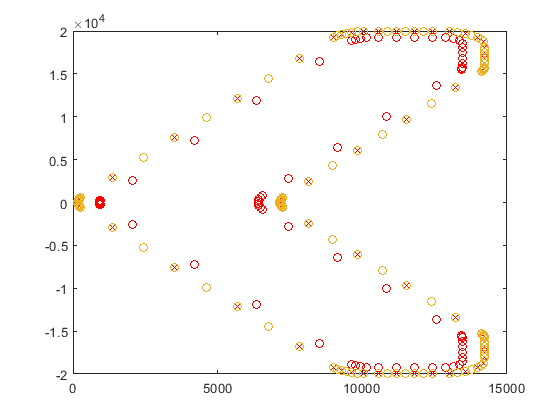

plot(x_midle, z_midle, 'xr',...
     x_midle_i, z_midle_i, 'ro',...
     x_midle_DE, z_midle_DE, 'o')

% xlim([-0.1+0.8 0.3+0.8])
% ylim([0.8 1.2])